clear all
load ARTEMIS_road.mat;
start=1;%Definisci l'istante iniziale
N=5; %Time horizon
u=[];
%definisci le opzioni per l'optimisation
opts=optimoptions('fmincon','MaxFunctionEvaluations',1e3,...
    'Algorithm','sqp','ConstraintTolerance',1e-3,'Display','none');
    
ARTEMIS=ARTEMIS_road;
%Simuli su finestre di 5 secondi per avere un'idea di come simulerebbe nel
%lungo periodo senza che ci metta 200 ore ogni volta. Non è MPC è solo per
%vedere i risultati pratici

SOC=0.55*ones(N);
for j=1:100
    %Estrai i sottovettori e ridefinisci gli handle per i sottovettori.
    %Stavolta la funzione di costo è calcolata tutta in una volta. Bisogna
    %rivedere la funzione di costo bene
    speed=ARTEMIS(1,start+(j-1)*N:start+N-1+(j-1)*N);
    acceleration=ARTEMIS(2,start+(j-1)*N:start+N-1+(j-1)*N);
    gear=ARTEMIS(3,start+(j-1)*N:start+N-1+(j-1)*N);
    
    StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input);
    FullStateUpdate=@(u)full_horizon(u,SOC(end),StateUpdate);
    nonlinconstr_h=@(u)nonlinconstr(u,SOC(end),StateUpdate);
    %calcoli la u ottima sull'orizzonte dei 5 secondi
    tic
    [u_n,fin_cost(j),exitf(j),output(j)]=fmincon(FullStateUpdate,0.3*ones(N,1),[],[],[],[],...
        -1*ones(N,1),ones(N,1),nonlinconstr_h,opts);
    toc
    %salvi la u per poi vedere il risultato complessivo
    u=[u;u_n];
    if exitf(j)<=0
        j
        exitf(j)
    end
    [~,SOC]=FullStateUpdate(u_n);
end

Ci ha messo 0.624452           
Ci ha messo 1.920469           
Ci ha messo 0.469553           
Ci ha messo 0.390462           
Ci ha messo 0.731598           


%Vedi i risultati utilizzando la u trovata nell'intero orizzonte
speed=ARTEMIS(1,start:start+N-1+(j-1)*N);
acceleration=ARTEMIS(2,start:start+N-1+(j-1)*N);
gear=ARTEMIS(3,start:start+N-1+(j-1)*N);
StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input);
FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
[cost,SOC,T_req,T_giv,mf,I_c,V_c]=FullStateUpdate(u);
[c,ceq]=nonlinconstr(u,0.55,StateUpdate);
tot_c=sum(sum(c<=0))/(2*length(c))

tot_c = 1.9970

tot_ceq=sum(abs(ceq)<=opts.ConstraintTolerance)/length(ceq)

tot_ceq = 1

tot_mf=sum(mf)

tot_mf = 0.1502

tot_soc_var=SOC(1)-SOC(end)

tot_soc_var = 0.0293

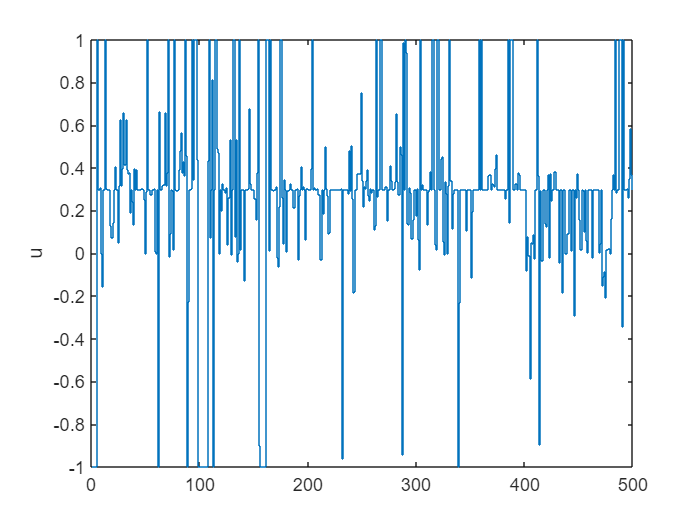


stairs(u)
ylabel('u')

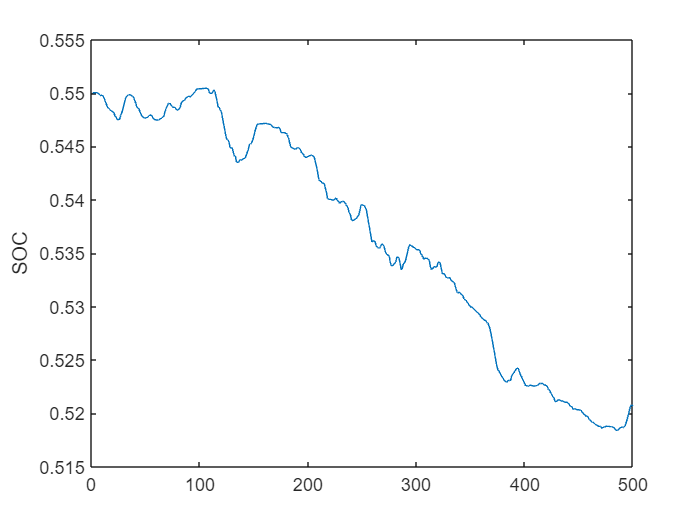

plot(SOC)
ylabel('SOC')

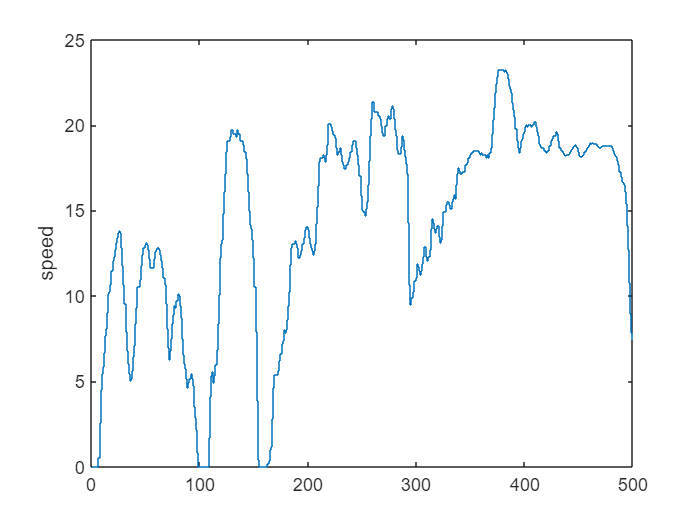

stairs(speed)
ylabel('speed')

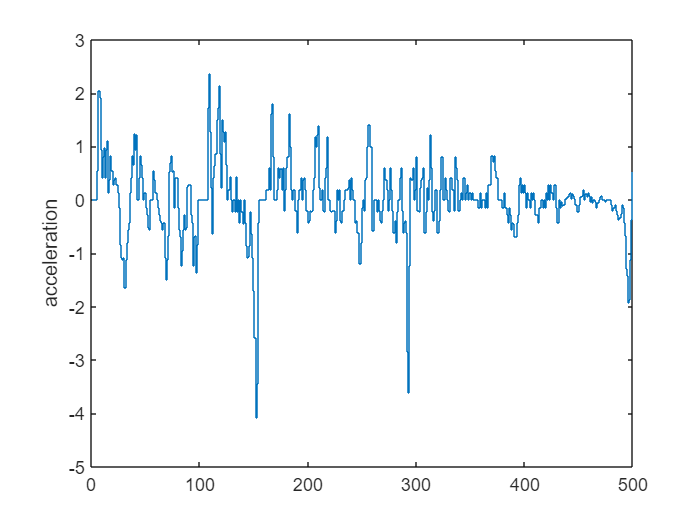

stairs(acceleration)
ylabel('acceleration')

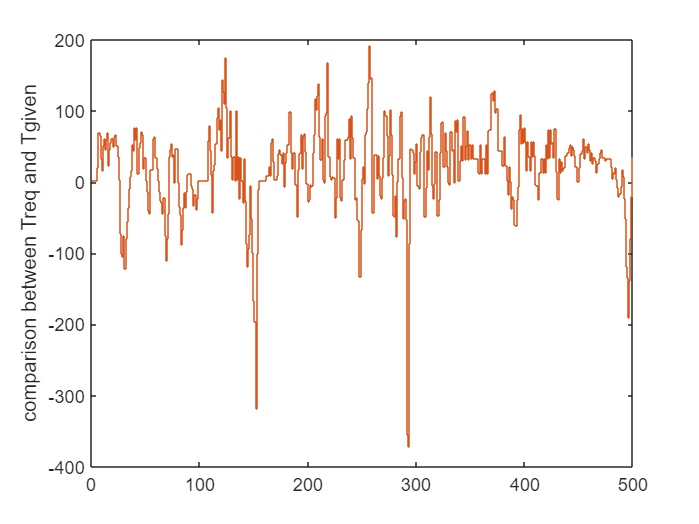

stairs(T_giv)
hold on
stairs(T_req)
hold off
ylabel('comparison between Treq and Tgiven')